# LAB 7: STATE-SPACE DESIGN FOR POSITION CONTROL IN A DC MOTOR

%---------------------------------------
% Fill in your student Name and ID.
Students.Name = 'Hongtao Xu';
Students.ID = '260773785';
%---------------------------------------

## **0. Objectives**

In this lab, we will experiment with different controller design to regulate the angular position of a DC Motor. For this we will use state-space representation in `MATLAB` and the function **lsim** to simulate the response of continuous linear systems to arbitrary inputs.

In section 1, we will define the DC Motor model. In section 2, we will design an output feedback controller for angular position control. In section 3, we will study the effect of model mismatch on the output feedback control. Finally, in section 4, we will design a state feedback with an integral component to reduce the disturbance effects.

## **1. State-Space Representation of a DC Motor**

A DC motor can be characterized by the following parameters:

param.Kt = 0.035; % Torque proportionality constant (Kg m2 /s2/A) (N.m/A)
param.Ke = 0.035; % Back electromotive proportionality constant (V/rad/s)
param.L = 5e-3; % Electric inductance (H)
param.R = 0.1; % Terminal resistance (Ohm)
param.J = 5e-4; % Rotor moment of inertia (kg.m2)
param.b = 1e-06; % Rotor viscous friction constant (Kg.m2/s) (N.m.s)

Notice that these parameters differ from the one used for the hardware Qnet DC Motor, and are chosen for the purpose of this lab experiments. The complete state of the DC Motor is represented by $x(t)$


$$ x(t) = \pmatrix{ \theta(t) \cr \omega(t) \cr i(t) } $$


where $\theta(t)$ is the angular position of the rotor, $\omega(t)$ is the angular velocity, and $i(t)$ is the current. The state-space representation of the DC Motor can be written as.


$$ \displaystyle \frac{d}{dt}x(t) = \pmatrix{ 0 & 1 & 0  \cr  0 & -\displaystyle \frac{b}{J}
& \displaystyle \frac{K_t}{J} \cr  0 & -\displaystyle \frac{K_e}{L} &
-\displaystyle \frac{R}{L} } x(t) + \pmatrix{ 0 \cr 0 \cr \displaystyle
\frac{1}{L} } v(t) $$


We are interested on controlling the angular position $$ \theta(t) = \pmatrix{ 1 & 0 & 0} x(t) $$ to track a step input of 90 degrees.

The state-space representation of the DC Motor can be written as.

A = [ ...
    0, 1, 0; ...
    0, -param.b / param.J, param.Kt / param.J; ...
    0, -param.Ke / param.L, -param.R / param.L];
B = [ ...
    0; ...
    0; ...
    1 / param.L];
C = [1, 0, 0];
D = 0;

## **2. Position Control with Output Feedback**

## *2.1 Full state feedback*

In this section we assume that the state $x(t)$ is available at any time. Thus, we will design a state feedback controller of the form:


$$v(t) = -K x(t) + N r(t)$$


<<fig_lab07_full_state_feedback.png>>

## *Question 1 (0.5 marks)*

Is the system controllable in the proposed state representation?

% [Answer here]; 
ck = [B A*B A*A*B]

ck = 	1.0e+05 *

         0         0    0.1400
         0    0.1400   -2.8003
    0.0020   -0.0400   -0.1800


controllable = det(ck)

controllable = -3.9200e+10

%the system is controllable because the det(ck) not equal to 0.

## *Question 2 (2 marks)*

- Design the feedback gain K such that the state feedback places the closed-loop poles at the following locations: $-15 \pm 15 j$, and -150.

- Find the value of the pre-compensator N that will make the steady state error 0.

- Complete the code to test the designed state-feedback controller.

% 1 - [Answer here]
 syms s
 I=eye(3);
 curChar = det(s*I-A);
 desCharN = (s+150)*(s+15+15i)*(s+15-15i);
 desCharS = expand(desCharN);
 Akhat = [0 1 0; 0 0 1; 0 -12251/25 -10001/500];
 Bkhat = [0; 0; 1];
 ckhat = [Bkhat Akhat*Bkhat Akhat*Akhat*Bkhat];
 Tkhatinv = ckhat*inv(ck);
 Khat = [67500 4950-(12251/25) 180-(10001/500)];
 Kpoles = [-15+15i -15-15i -150];

 K = Khat*Tkhatinv

K =     4.8214    0.3185    0.8000



Kpoles = -[-15+15j -15-15j -150]

Kpoles = 	1.0e+02 *

   0.1500 - 0.1500i   0.1500 + 0.1500i   1.5000 + 0.0000i



K_hat_2 = place(A,B,Kpoles);
DCGaink = C*inv(-A+B*K)*B

DCGaink = 0.2074

% 2 - [Answer here]

N = 1/DCGaink

N = 4.8214

% 3 - [Answer here]

dt = 1e-3; % sampling time
t = 0:dt:2; % time signal
r = 90 * pi / 180 * ones(size(t)); % reference signal
syms s 
I = eye(3);
% define the closed loop system
Hcl = ss((A-B*K),B,C,D)


Hcl =
 
  A = 
           x1      x2
   x1       0       1
   x2       0  -0.002
   x3  -964.3  -70.71
 
           x3
   x1       0
   x2      70
   x3    -180
 
  B = 
        u1
   x1    0
   x2    0
   x3  200
 
  C = 
       x1  x2  x3
   y1   1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



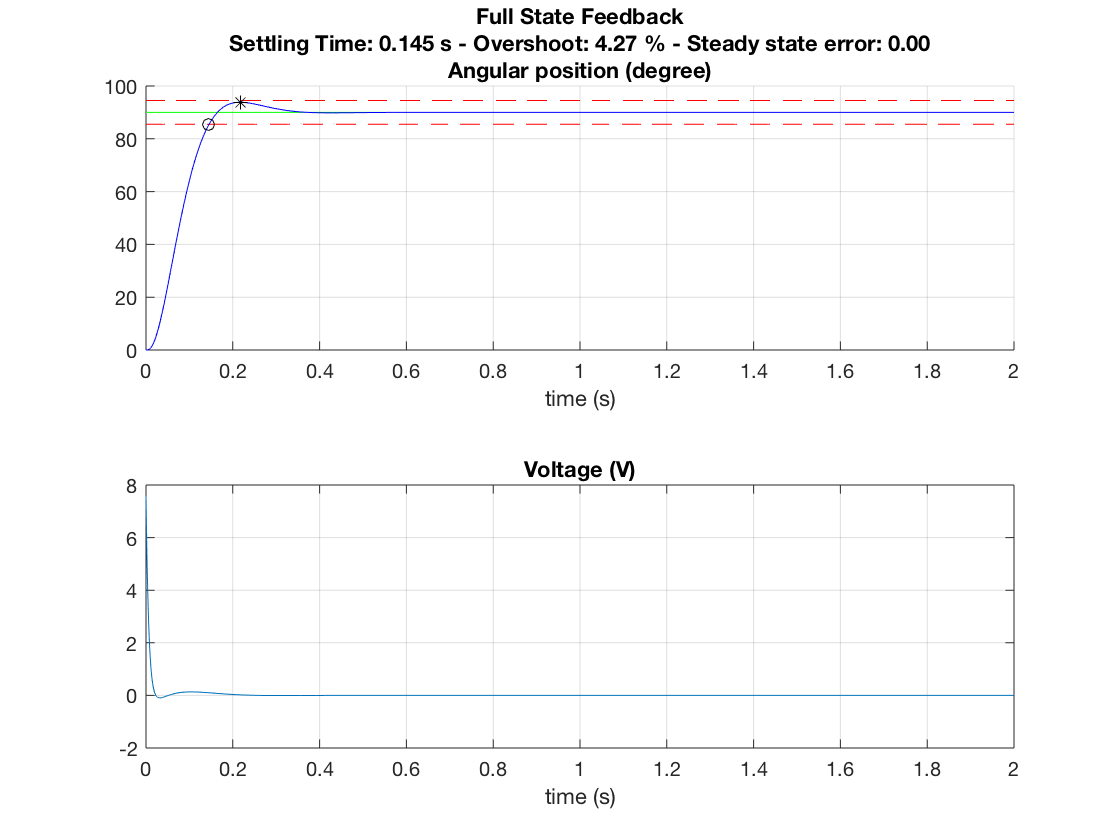


w = lsim(Hcl, N*r, t)'; % simulate the output
v = -K * lsim(ss(Hcl.A, Hcl.B, eye(3), 0), N*r, t)' + N * r; % simulate the command

customStep(sprintf('Full State Feedback'), t, w, r, v)

## *2.2 Output feedback with state observer*

We assume that the state can't be fully measured and only the angular position can be measured. We will design a Luenberger observer based on the known model and the output $\theta(t)$. Recall that the equations of Luenberger observer are:


$$ \displaystyle \frac{d}{dt}\hat{x}(t) = A\hat{x}(t) + B v(t) + L ( C
x(t) - C \hat{x}(t) ) $$


where $L$ is the Luenberger gain.

<<fig_lab07_output_feedback.png>>

## *Question 3 (0.5 marks)*

Is the system observable in the proposed state representation?

% [Answer here]
Ol = [C; C*A; C*A*A]

Ol =     1.0000         0         0
         0    1.0000         0
         0   -0.0020   70.0000


Observable = det(Ol)

Observable = 70

% the observable is not equal to 0 so that it is observable

## *Question 4 (1 marks)*

Design a Luenberger state estimator such that the eigenvalues of the observer are $-10 \pm 10 j$, and -100.

% the 3 roots are s - -10+10j; s - -10+10j and s - - 100
Lpoles = [-10-10i; -10+10i; -100]

Lpoles = 	1.0e+02 *

  -0.1000 - 0.1000i
  -0.1000 + 0.1000i
  -1.0000 + 0.0000i


% given AhatL and ChatL
% Olhat = [chatL; chatL; chatL*AhatL*AhatL]
% T1hat = invert * 01hat
% we got Lhat and L=T1hat*hat

L = place(A',C',Lpoles)'

L =    99.9980
 -290.2000
 -331.4146


The state space representation of the output feedback system with a state observer can be represented by the augmented state:


$$ x_{aug}(t) = \pmatrix{ x(t) \cr \hat{x}(t)} $$


and the feedback law is:


$$ v(t) = -K \hat{x}(t) + N r $$


With these notations, we can write the augmented state space equations as a function of A, B, C, K, and L


$$ \displaystyle \frac{d}{dt}x_{aug}(t) = \pmatrix{ A & -B K \cr L C & A
- L C - B K} x_{aug}(t) + \pmatrix{B \cr B} v(t) $$


## *Question 5 (1.5 marks)*

- Write the augmented state-space representation matrices $A_{aug}$ and $B_{aug}$.

- Complete the code to simulate the response of output feedback system to follow a step input (use the same feedback gain $N$, and $K$ from section 1.1).

% 1 - [Answer here]

Aaug = [A -B*K; L*C A-L*C-B*K]

Aaug =          0    1.0000         0         0         0         0
         0   -0.0020   70.0000         0         0         0
         0   -7.0000  -20.0000 -964.2857  -63.7091 -159.9980
   99.9980         0         0  -99.9980    1.0000         0
 -290.2000         0         0  290.2000   -0.0020   70.0000
 -331.4146         0         0 -632.8711  -70.7091 -179.9980



Baug = [B;B]

Baug =      0
     0
   200
     0
     0
   200




% 2 - [Answer here]
Caug = [1, 0, 0, 0, 0, 0];
dt = 1e-3

dt = 1.0000e-03

t = 0:dt:2

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


r = 90 * pi / 180 * ones(size(t));
% we have got sampling time, time signal, reference signal
Hcl = ss(Aaug,Baug,Caug,D)


Hcl =
 
  A = 
           x1      x2
   x1       0       1
   x2       0  -0.002
   x3       0      -7
   x4     100       0
   x5  -290.2       0
   x6  -331.4       0
 
           x3      x4
   x1       0       0
   x2      70       0
   x3     -20  -964.3
   x4       0    -100
   x5       0   290.2
   x6       0  -632.9
 
           x5      x6
   x1       0       0
   x2       0       0
   x3  -63.71    -160
   x4       1       0
   x5  -0.002      70
   x6  -70.71    -180
 
  B = 
        u1
   x1    0
   x2    0
   x3  200
   x4    0
   x5    0
   x6  200
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
       x5  x6
   y1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



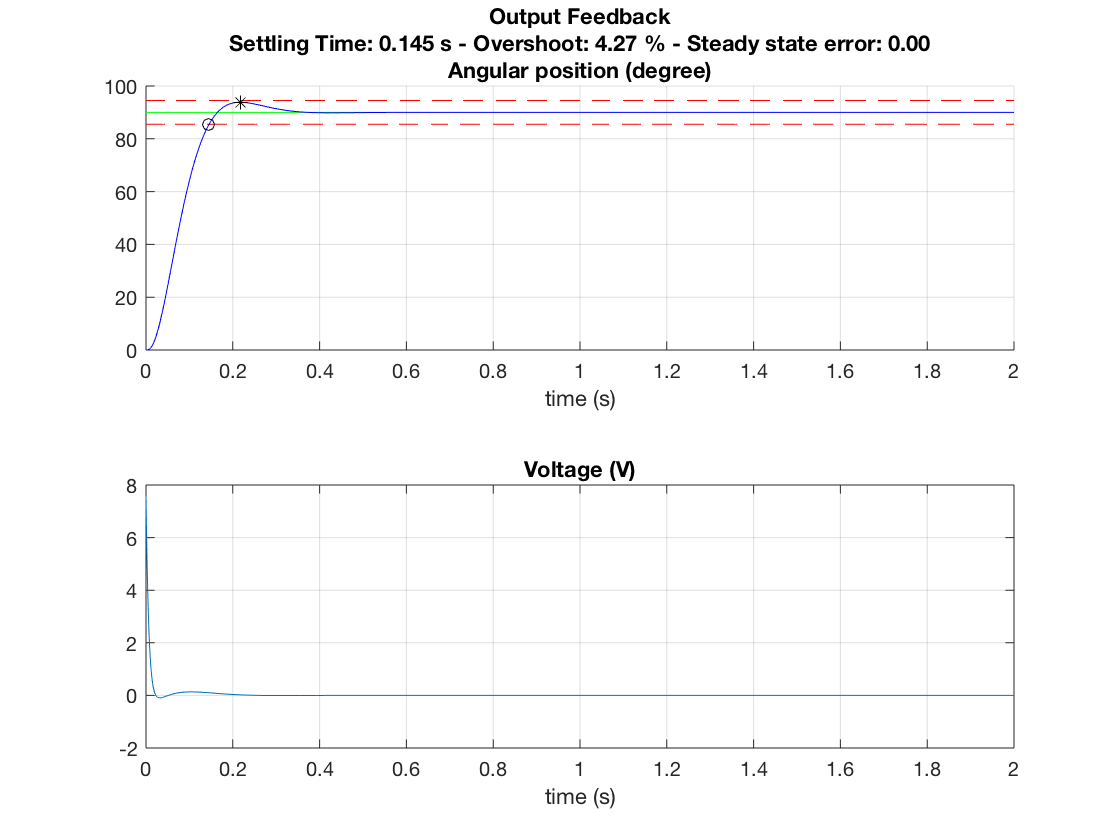


% define the augmented closed loop system
w = lsim(Hcl, N*r, t)';
% simulate the output
% make the output a row array

v = -K * lsim(ss(Hcl.A, Hcl.B, [zeros(3), eye(3)], 0), N*r, t)' + N * r; % simulate the command

customStep(sprintf('Output Feedback'), t, w, r, v)

## *Question 6 (1 marks)*

Let's change the Luenberger gain such as the observer dynamic is 10 times slower. re-run the experiment. What do you observe? Justify your answer.

Lnewpoles = 0.1 * Lpoles;

Lnew = place(A', C', Lnewpoles)';

K = place(A, B, Kpoles);

Aaug = [A -B*K; Lnew*C A-Lnew*C-B*K]

Aaug =          0    1.0000         0         0         0         0
         0   -0.0020   70.0000         0         0         0
         0   -7.0000  -20.0000  964.2857  -63.7194  200.0020
   -8.0020         0         0    8.0020    1.0000         0
 -307.9840         0         0  307.9840   -0.0020   70.0000
  144.2997         0         0  819.9860  -70.7194  180.0020



Baug = [B;B]

Baug =      0
     0
   200
     0
     0
   200


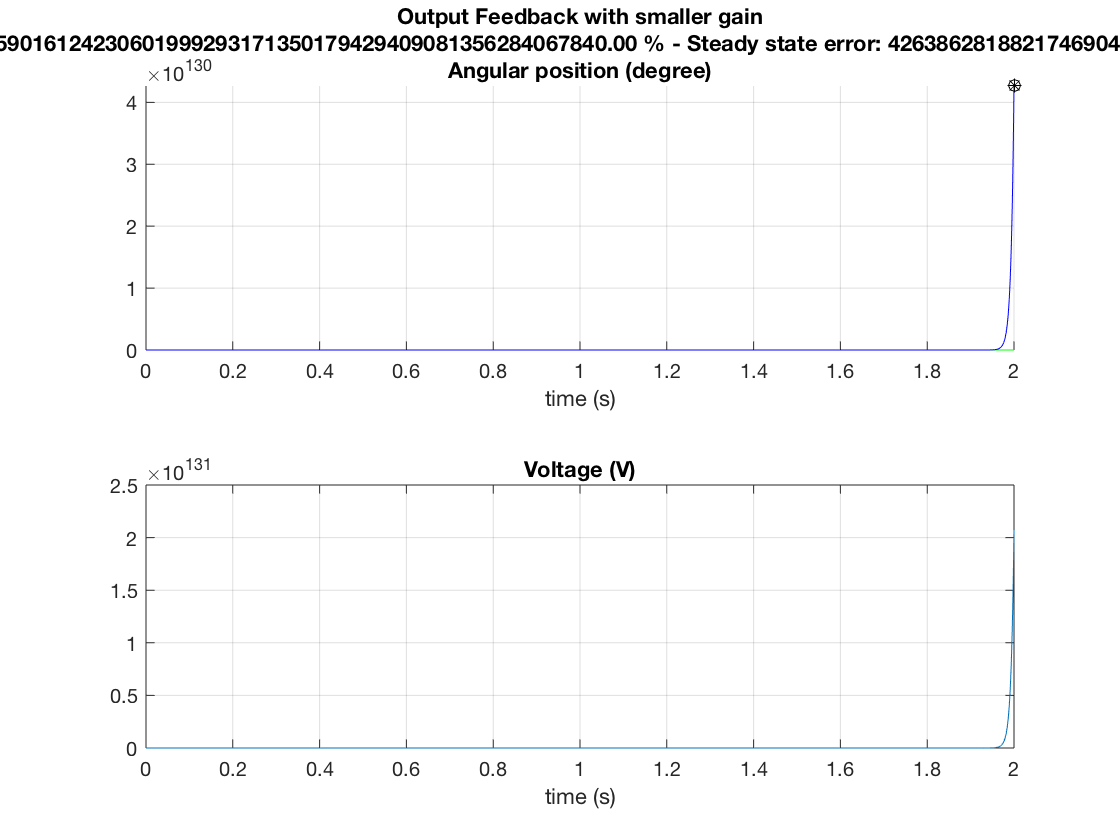


Caug = [1, 0, 0, 0, 0, 0];

Hcl  =ss(Aaug,Baug,Caug,D); % define the closed loop system
w = lsim(Hcl, N*r, t)'; % simulate the output


%w = w(:)'; % make the output a row array
v = -K * lsim(ss(Hcl.A, Hcl.B, [zeros(3), eye(3)], 0), N*r, t)' + N * r; % simulate the command

customStep(sprintf('Output Feedback with smaller gain'), t, w, r, v)

%  What do you observe?
%  the oberver dynamic speed does not change 

## **3. Effects of wrong model**

As seen in section 2 the importance of the Luenberger estimator will only be visible in case the dynamics of the model are not completely known. For example, in this section we assume that in the real DC Motor the inertia is 3 times what we initially thought. Which means that the true dynamics of the DC Motor are:

<<fig_lab07_estimator_wrong_model.png>>

Jreal = 3 * param.J;

Areal = [ ...
    0, 1, 0; ...
    0, -param.b / Jreal, param.Kt / Jreal; ...
    0, -param.Ke / param.L, -param.R / param.L];

For the purpose of this experiment we assume that we don't know about the true $A_{real}$ and we only use $A$ in the estimator dynamics.

## *Question 7 (1.5 marks)*

- Re-run the experiment using the same gains $N$, $K$, and $L$. But this time replace the transition matrix of the state space model of the DC Motor by $A_{real}$. What do you observe?

- Change the design of $L$ such as the observer is 5 times faster. What do you observe?

% 1 -

Aaug = [Areal -B*K; Lnew*C Areal-Lnew*C-B*K]

Aaug =          0    1.0000         0         0         0         0
         0   -0.0007   23.3333         0         0         0
         0   -7.0000  -20.0000  964.2857  -63.7194  200.0020
   -8.0020         0         0    8.0020    1.0000         0
 -307.9840         0         0  307.9840   -0.0007   23.3333
  144.2997         0         0  819.9860  -70.7194  180.0020



Baug = [B;B]

Baug =      0
     0
   200
     0
     0
   200



Hcl = ss(Aaug, Baug, Caug, D) % define the closed loop system


Hcl =
 
  A = 
               x1
   x1           0
   x2           0
   x3           0
   x4      -8.002
   x5        -308
   x6       144.3
 
               x2
   x1           1
   x2  -0.0006667
   x3          -7
   x4           0
   x5           0
   x6           0
 
               x3
   x1           0
   x2       23.33
   x3         -20
   x4           0
   x5           0
   x6           0
 
               x4
   x1           0
   x2           0
   x3       964.3
   x4       8.002
   x5         308
   x6         820
 
               x5
   x1           0
   x2           0
   x3      -63.72
   x4           1
   x5  -0.0006667
   x6      -70.72
 
               x6
   x1           0
   x2           0
   x3         200
   x4           0
   x5       23.33
   x6         180
 
  B = 
        u1
   x1    0
   x2    0
   x3  200
   x4    0
   x5    0
   x6  200
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
       x5  x6
   y1   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time st

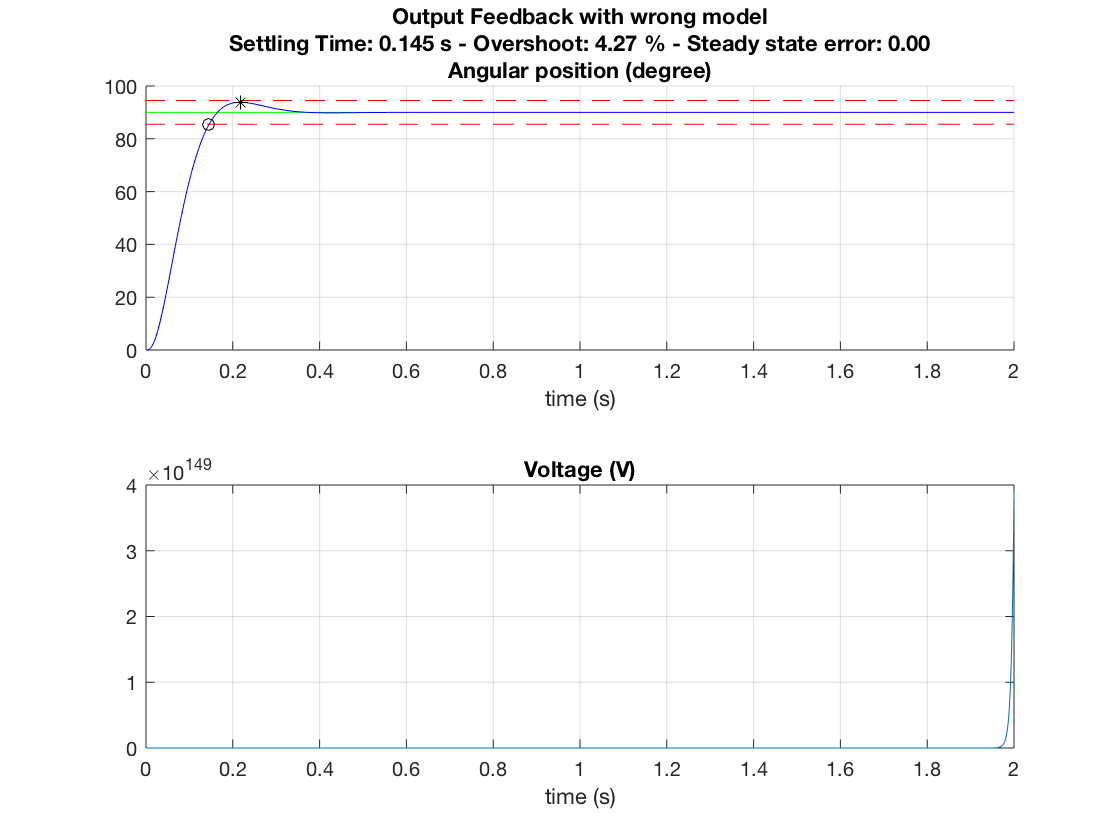

% simulate the output


w=w(:)';% make the output a row array
v = -K * lsim(ss(Hcl.A, Hcl.B, [zeros(3), eye(3)], 0), N*r, t)' + N * r; % simulate the command

customStep(sprintf('Output Feedback with wrong model'), t, w, r, v)

% What do you observe?
% for my assuption, the peak time and overshoot shoule be larger.the
% position is unstable in the end, the estimate changes. 

% 2 -

Lnewpoles = 5 * Lpoles % set this value to 5*Lpoles

Lnewpoles = 	1.0e+02 *

  -0.5000 - 0.5000i
  -0.5000 + 0.5000i
  -5.0000 + 0.0000i


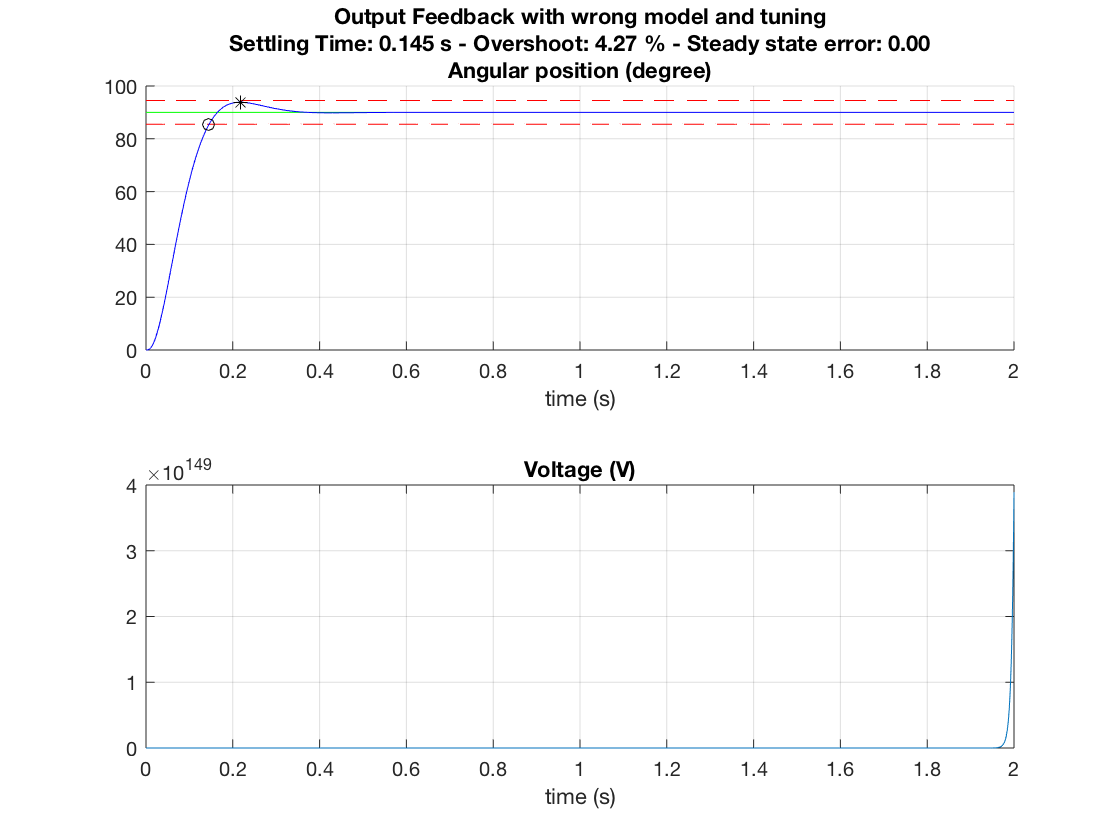


Lnew = place(A', C', Lnewpoles)';

K = place(A, B, Kpoles);

Aaug = [Areal -B*K; Lnew*C Areal-Lnew*C-B*K];

Baug = [B;B];

Hcl = ss(Aaug, Baug, Caug, D);% define the closed loop system
 % simulate the output


w=w(:)'; % make the output a row array
v = -K * lsim(ss(Hcl.A, Hcl.B, [zeros(3), eye(3)], 0), N*r, t)' + N * r; % simulate the command

customStep(sprintf('Output Feedback with wrong model and tuning'), t, w, r, v)

% What do you observe?
%the estimated output converges faster for the output, there is increase
%near 2. 

## **4. Disturbance and Integral Design**

## *4.1 Experiment with an additive disturbance*

In this section we want to study the effects of a voltage disturbance on the state feedback controller. For this, we will simulate the effects of an additive disturbance into the voltage command of value $d = 4 V$ at time = 1s.

To simplify the problem, we will consider that the whole state is available, that we know the exact model of the DC Motor (same in section 1), and that we have designed a full feedback controller $K$, and $N$.

## Question 8 (0 marks)

What do you expect to happen to the angular position of the DC motor after applying a voltage command $d = 4 V$ at time = 1s?

% [Answer here]
% we put d = 4v as input, leading to motor position overturn at certain
% angle 

Let's simulate the result of adding such a disturbance in the closed-loop system

K = place(A, B, Kpoles);

d = zeros(size(t));
d(t >= 1) = 4; % disturbance signal

Hcl = ss(A-B*K, B, C, 0); % define the closed loop system
w = lsim(Hcl, N*r+d, t)'; % simulate the output
v = -K * lsim(ss(Hcl.A, Hcl.B, eye(3), 0), N*r+d, t)' + N * r + d; % simulate the command

customStep(sprintf('State Feedback with disturbance'), t, w, r, v)

## Question 9 (0.5 marks)

What is the steady state error? What is the closed-loop system type?

% [Answer here]
% for assupmetion, the steay error is pretty big, there is a type 0 system
%if the error stays at constant value

## *4.2 state feedback with integral term*

We can add an integral term to the feedback controller to increase the type of the system. The integral equation is


$$ x_n(t) = r(t) - C x(t) $$


The augmented system is


$$ x_{aug}(t) = \pmatrix{ x(t) \cr x_n(t)} $$


and the feedback law is:


$$ v(t) = -K x(t) + K_e x_n(t) $$


The equivalent system can be seen as a closed-loop system where the open-loop dynamics is defined by


$$ \tilde{A} = \pmatrix{ A & 0 \cr -C & 0} $$



$$ \tilde{B} = \pmatrix{ B \cr 0} $$


and a unity feedback


$$ v(t) = -\pmatrix{ K & -K_e} x_{aug}(t)$$


## Question 10 (1.5 marks)

- Design $K$ and $Ke$ such as the poles of the feedback system are: $-15 \pm 15 j$, and $-150 \pm 150 j$.

- Complete the code to run the simulation.

- What do you observe?

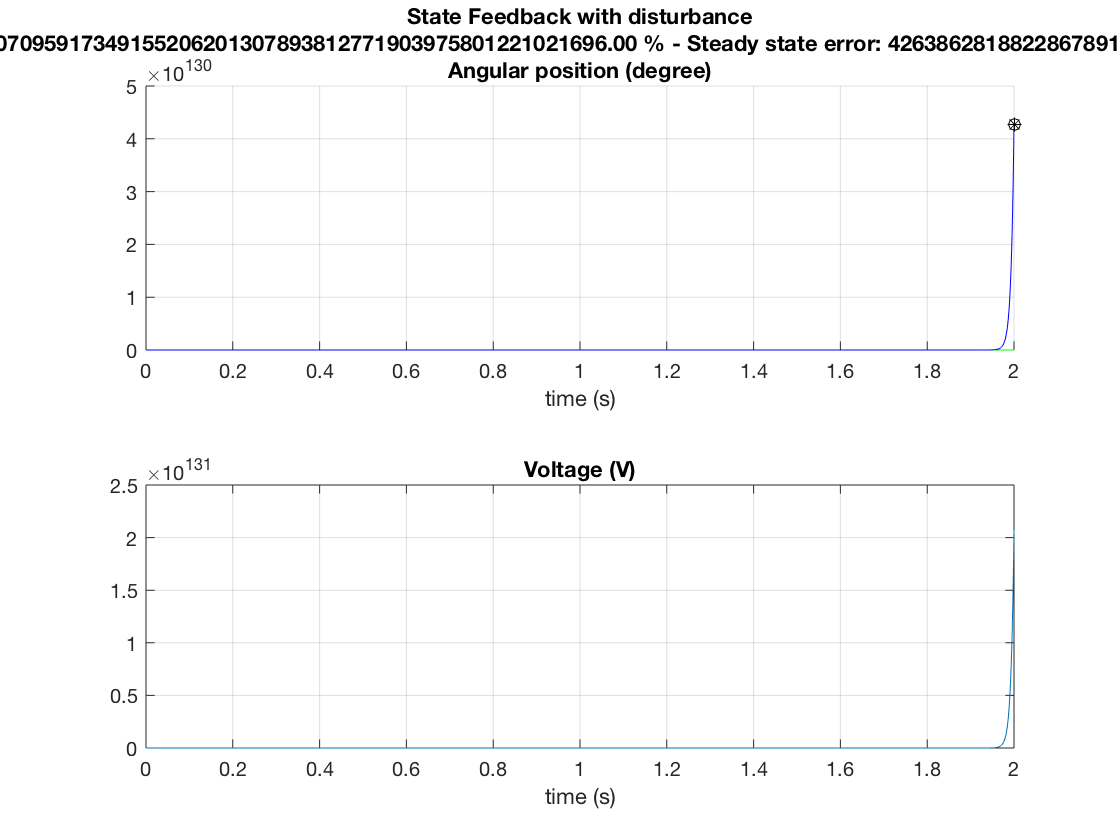

% 1 - [Answer here] use place in the augmented closed-loop with integral
% system

p1d = -15 + 15i;
p2d = -15 - 15i;
p3d = -150 * (1 + 1i);
p4d = -150 * (1 - 1i);

Atilde = [A [0;0;0]; -C 0];
Btilde = [B;0];
Kall = place(Atilde,Btilde,[p1d,p2d,p3d,p4d]);
Ke = -Kall(1,end);
K = Kall(1,1:3);

% 2 - Run the experiment

d = zeros(size(t));
d(t >= 1) = 4; % disturbance signal

% define the augmented closed-loop system

AtildeCl = Atilde - Btilde*Kall;

% simulate the output
yr = lsim(ss(AtildeCl, [0; 0; 0; 1], [1, 0, 0, 0], 0), r, t)'; %response to reference
yd = lsim(ss(AtildeCl, Btilde, [1, 0, 0, 0], 0), d, t)'; %response to disturbance
w = yr + yd;

v = -[K, -Ke] * lsim(ss(AtildeCl, [[0; 0; 0; 1], Btilde], eye(4), 0), [r; d], t)' + d; % simulate the command

customStep(sprintf('Integral State Feedback with disturbance'), t, w, r, v)

% 3 - What do you observe?
%The steady state error of the model is gone.

## **5. Useful Functions**

## *5.1 Custom step response*

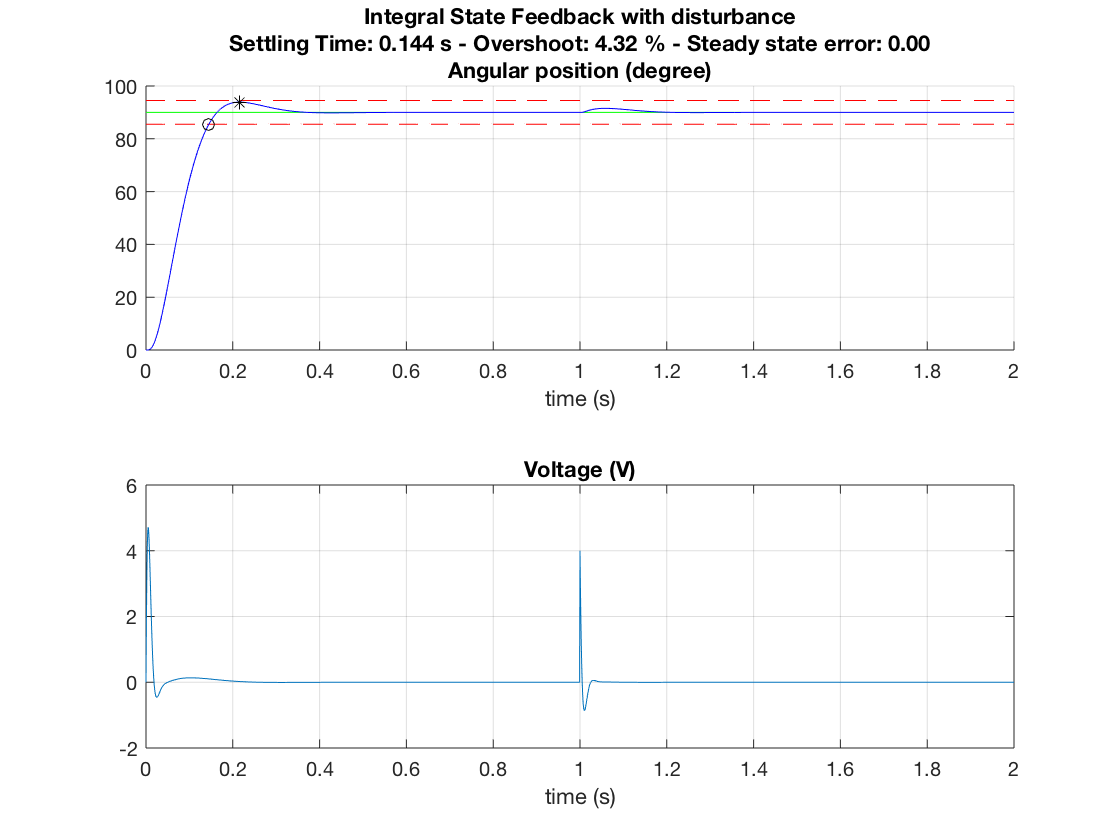

function customStep(figTitle, t, w, r, v)
% calculate response characteristics and plot results
settlingTimeIdx = find(round((w - 0.95 * r)*180/pi, 1) <= 0.05 | round((w - 1.05 * r)*180/pi, 2) >= -0.05, 1, 'last');
[~, overshootIdx] = max(w);
steadyStateError = (180 / pi) * (w(end) - r(end));

figure;
clf;
hold on;
subplot(2, 1, 1)

hold on;
plot(t, (180 / pi)*0.95*r, '--r');
plot(t, (180 / pi)*1.05*r, '--r');
plot(t, (180 / pi)*r, 'g');
plot(t, (180 / pi)*w, 'b');
plot(t(settlingTimeIdx), (180 / pi)*w(settlingTimeIdx), 'ok')
plot(t(overshootIdx), (180 / pi)*w(overshootIdx), '*k')
grid on;
title(sprintf(['%s\n', ...
    'Settling Time: %4.3f s - Overshoot: %03.2f %% - Steady state error: %3.2f\n', ...
    'Angular position (degree)'], ...
    figTitle, ...
    t(settlingTimeIdx), ...
    100*(w(overshootIdx) - r(end))/r(end), ...
    steadyStateError))
xlabel('time (s)')
subplot(2, 1, 2)
plot(t, v);
grid on;
title('Voltage (V)');
xlabel('time (s)')
drawnow;
end